# Lecture 3: Digital Image Fundamentals

# Part 5: Scaling Issues

Author: Dr. Zeynep Cipiloglu Yildiz

Notes:

- Sample images are available in both Matlab IPT *imdata* folder and *images* folder in the current directory. (You may need to add images folder into your path.)

- Related lecture: Lecture3 - Digital Image Fundamentals

- pdf versions of the .mlx files are also available for those using GNU Octave

% clear workspace variables and close windows
clc, clearvars, close all;

I1 = imread('cameraman.tif');
I2 = imread('circles.png');
I1 + I2; % this operation is not allowed

Error using  + 
Integers can only be combined with integers of the same class, or scalar doubles.

I2u = uint8(I2); % convert I2 to the same class with I1
max(I2u(:))

ans = uint8
1

I2u = 255*I2u; % scale it to the same range
I3 = I1+I2u; % now it is allowed
max(I3(:)) % is something wrong?

ans = uint8
255

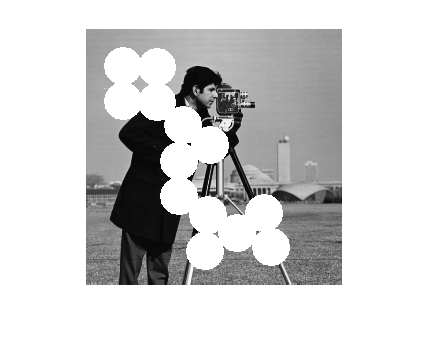

imshow(I3)

% convert images to double to perform arithmetic operations
I1d = double(I1);
I2d = double(I2u);

I3d = I1d+I2d;
max(I3d(:))

ans = 507

imshow(I3d) % what is wrong?

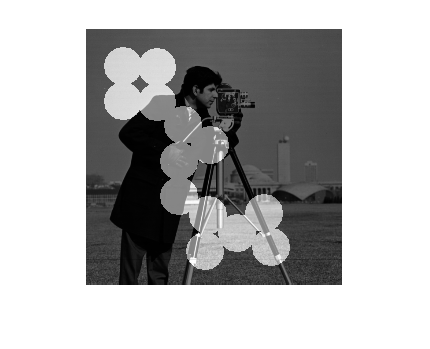

imshow(I3d,[])

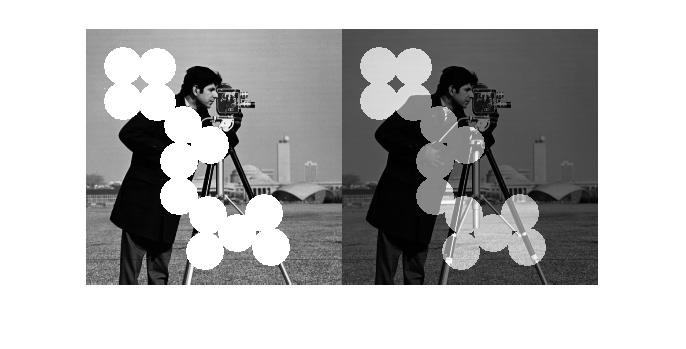

imshowpair(I3, I3d,'montage')